# Least Squares Properties Investigation

a) Generating input-output data with N=100;

clear all;
clc;

% defining parameters
N = 100;  %number of samples
rng("16600919")
u = ((2 * rand(1,N)) - 1)';  %system input
e = randn(1,N)';   %system noise
theta = [1.6; 0.8; 1; 0.7]

theta =     1.6000
    0.8000
    1.0000
    0.7000


% generating y
y = zeros(1,N)';

for k=3:N
    y(k) = ([y(k-1), - y(k-2), u(k-1), u(k-2)] * theta) + e(k);
end

% Plotting input-output data
figure;
plot(1:N,y,'b',LineWidth=2)
hold on;
plot(1:N,u,'k',LineWidth=2)
grid on;
legend('Output', 'Input')
xlabel('Time [sample index]')
ylabel('Output and Input')
title("Input and Output Signals")

**b) Estimating the parameters of the ARX model**

Y = y(3:end);
Phi = [y(2:end-1), -y(1:end-2), u(2:end-1), u(1:end-2)];
thetahat = Phi\Y;

**c) Estimating the confidence interval of the parameter estimates and critically analysing results.**

% First we get the residuals from the one step ahead prediction
ypred = Phi * thetahat;
res = y(3:end) - ypred; %next calculate the residuals

errorvariance = (1/(N-2-4)) * (res'*res);
covtheta = errorvariance * inv(Phi'*Phi);
SEtheta = sqrt(diag(covtheta));

confband95 = 1.96 * SEtheta;
theta_conf_bound = [thetahat - confband95, thetahat + confband95]

theta_conf_bound =     1.5756    1.7297
    0.7392    0.8969
    0.8035    1.5478
    0.2959    1.0945


**Plotting Confidence regions**

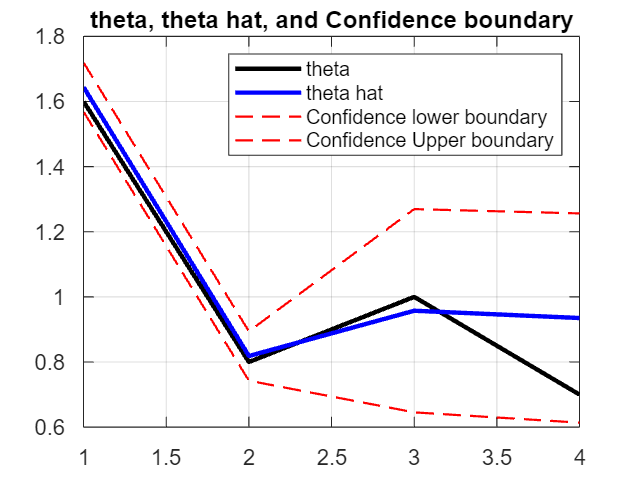

figure;
plot(1:4, theta, 'k-', LineWidth=2)
grid on
hold on
plot(1:4, thetahat, "b-", LineWidth=2)
plot(1:4, theta_conf_bound, 'r--', LineWidth=1)
legend("theta", "theta hat", "Confidence lower boundary", "Confidence Upper boundary")
title("theta, theta hat, and Confidence boundary")
hold off

## d) Computing One Step ahead prediction and Simulated Output

One Step Ahead Prediction (ypred) has already been computed to get the confidence interval

ypred; %one step ahead prediction

%simulated output

ysim = zeros(1,N);

for k = 3:N
    ysim(k) = [y(k-1), -y(k-2), u(k-1), u(k-2)] * thetahat;
end

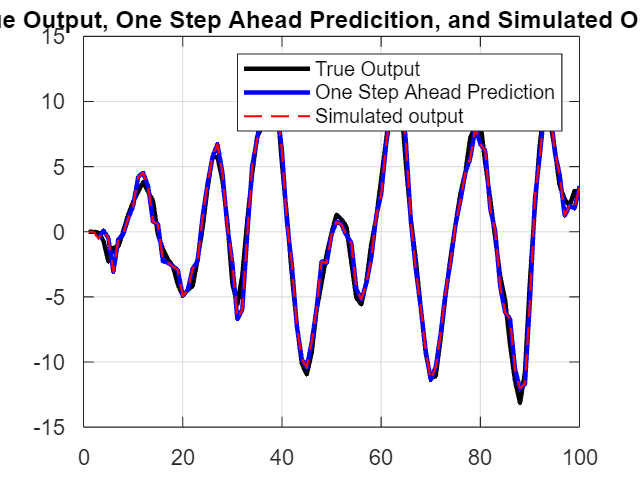

figure;
plot(1:N, y, 'k-', LineWidth=2)
grid on
hold on
plot(3:N, ypred, "b-", LineWidth=2)
plot(1:N, ysim, 'r--', LineWidth=1)
legend("True Output", "One Step Ahead Prediction", "Simulated output")
title("True Output, One Step Ahead Predicition, and Simulated Output")
hold off

## Computing Goodness of Fit Measures

**R-Squared - Coefficient of Determination**

**Mean Squared Error**

**Integral Absolute Error**

epsilon = y(3:end) - ypred;
R2pred = 100*(1-var(epsilon)/var(y(3:end)))

R2pred = 97.7627

MSE = sum((y(3:end)-ypred).^2)/N

MSE = 0.8050

IAE = sum(abs(y(3:end)-ypred))/N

IAE = 0.7227

## Residual Analysis

1. Residual Plot

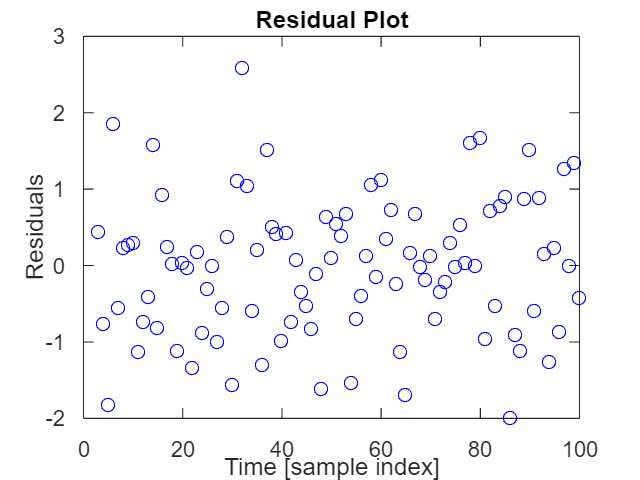

figure;
plot(3:N, epsilon, 'bo')
xlabel("Time [sample index]")
ylabel("Residuals")
title("Residual Plot")

2) Histogram of Residuals

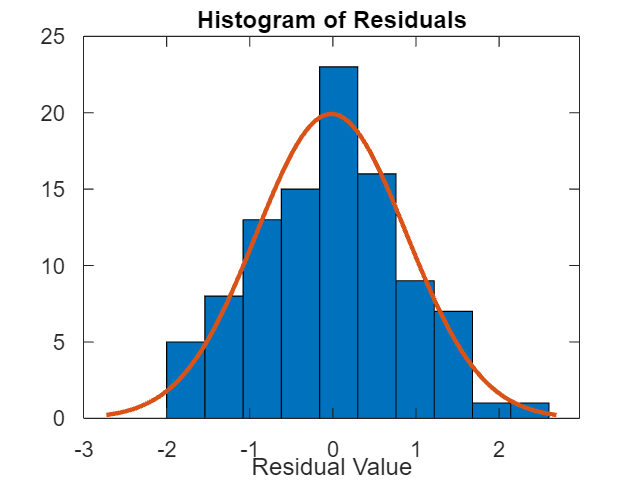

% histogram of residuals
figure;
histfit(epsilon);
title('Histogram of Residuals');
xlabel('Residual Value');

2. Auto Correlation and Cross Correlation

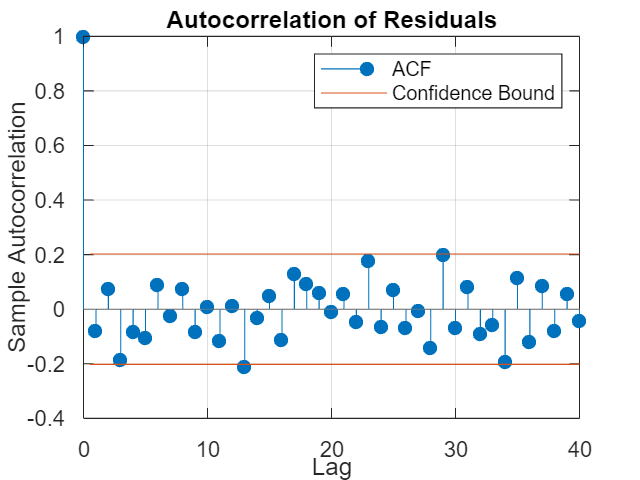

figure;
% autocorrelation of residuals
autocorr(epsilon, 'NumLags', 40);
title('Autocorrelation of Residuals');

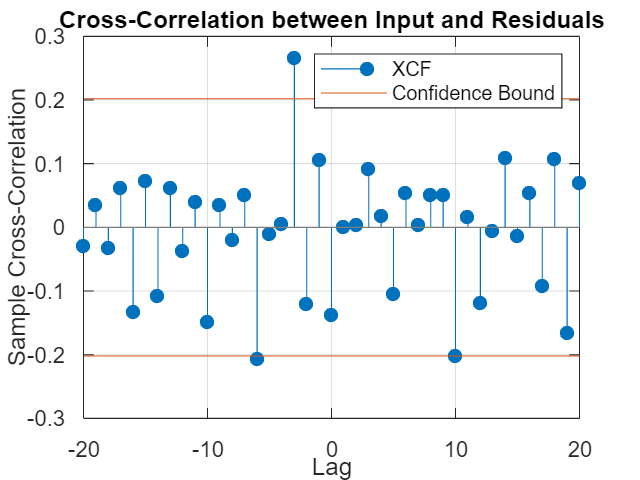


%crosscorrelation of residuals with input
figure;
crosscorr(u(3:end),epsilon)
title('Cross-Correlation between Input and Residuals');